We explore the seperation of zonally elongated transients (Rudko et al., 2018) from the background turbulent flow by applying EOF to the zonal velocity field in the Gulf Stream region. The original data has a grid spacing of 2km and time step of 0.5d. Here the data we used are subsampled onto a corase grid with 40km and 1d.

%---------------------------
%       read grid
%---------------------------
clear
if ~exist('plon','var')
    hycom_domain = 'GSH';
    read_HYCOM_grid;
end

%---------------------------
%  params for reading data
%---------------------------
% params set by you
% May14/yr8,  D460: Apr14/yr9 135, 490
[day_s,day_e] = deal(130, 490); % better start no earlier than D135 (May 15, datevec(135))
klay = 1;
MeanVelPath = '/projects2/rsmas/ikamenkovich/yxl1496/OTPT_148DEG/COARSE_SMOOTH/Z01/';
coarse_file = '_geostr_D002_499'; % _smdeg02_D002_499

% time coordinate
day_interv = day_e - day_s;
dt_ori = 1;
tuv = day_s:dt_ori:day_e;
ntuv = day_interv/dt_ori+1;

% region (A) to be studied
[jA, iA] = deal(101:20:JDM-200, 101:20:IDM-300); % 0.02deg * 20 = 0.4deg
[nj,ni] = deal(numel(jA),numel(iA));

scvx = scvx(jA,iA);
scuy = scuy(jA,iA);

%---------------------------
%  read mean velocities
%---------------------------
[uGSm,vGSm] = deal(zeros(nj,ni,ntuv));
% 
disp(['Loading mean velocity from: ',MeanVelPath,'xGS' coarse_file '.dat']);
% preallocate mean vel. Note Vm no miss
fidum=fopen([MeanVelPath,'uGS' coarse_file '.dat'],'r');
fidvm=fopen([MeanVelPath,'vGS' coarse_file '.dat'],'r');
for nind=1:size(uGSm,3)
    % nd locates the pointer in the file
    % '-2' in the bracket is because the 1st data in meanVel file is at day2
    nd=nind+(day_s-2)*2;
    fseek(fidum,4*(IDM*JDM)*(nd-1),-1);
    uv1d=fread(fidum,IDM*JDM,'float32','ieee-be');
    uv2d = reshape(uv1d,[JDM,IDM]);
    uGSm(:,:,nind) = uv2d(jA,iA);
    %
    fseek(fidvm,4*(IDM*JDM)*(nd-1),-1);
    uv1d=fread(fidvm,IDM*JDM,'float32','ieee-be');
    uv2d = reshape(uv1d,[JDM,IDM]);
    vGSm(:,:,nind)=uv2d(jA,iA);
end
fclose('all');

%---------------------------
%       do EOF
%---------------------------
field = uGSm;
[EOF,PC,expvar] = eof(field);
expvar(1:3)
    
% t - p_nonan, eliminate NaN points
X = reshape(field,[nj*ni,ntuv])';
NanMatrics = isnan(X);      
NanVec = any(NanMatrics,1); 
NanIndx = find(NanVec==1); 
X(:,NanIndx) = []; 
% cov & corr mat
covmat = cov(X);
cormat = corrcov(covmat);


The first three components are shown below. They explain 40% of the total variance. The EOF maps are dimensionless. 

The zonally elongated transient flow patterns near Gulf Stream are extracted in the first component. Note that this structure should be distinguished from the stationary zonal jets which has been subtracted before applying EOF. 

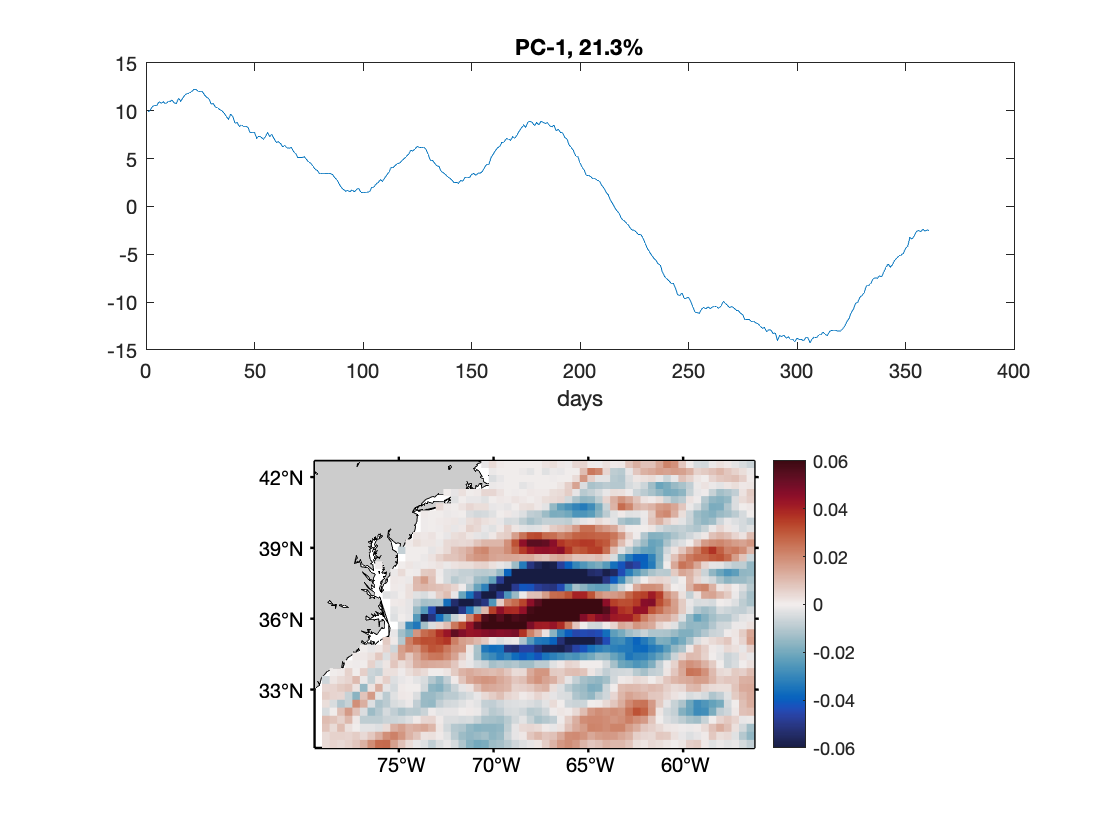

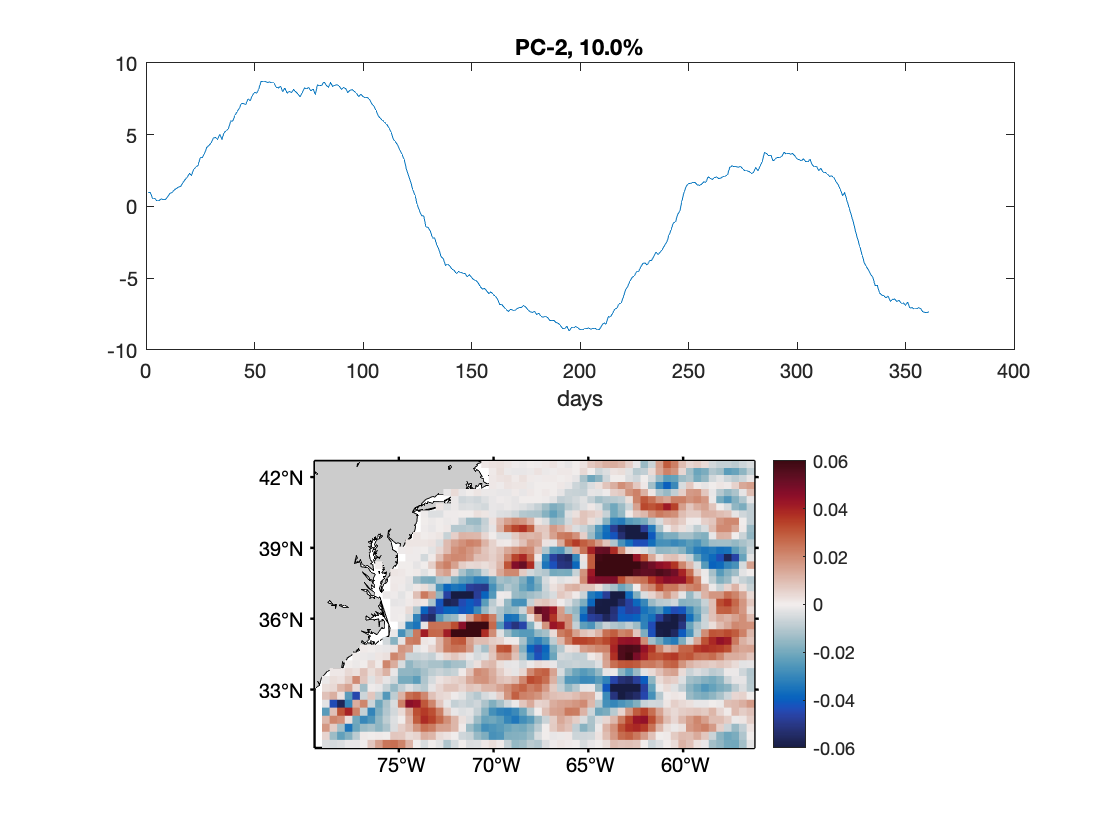

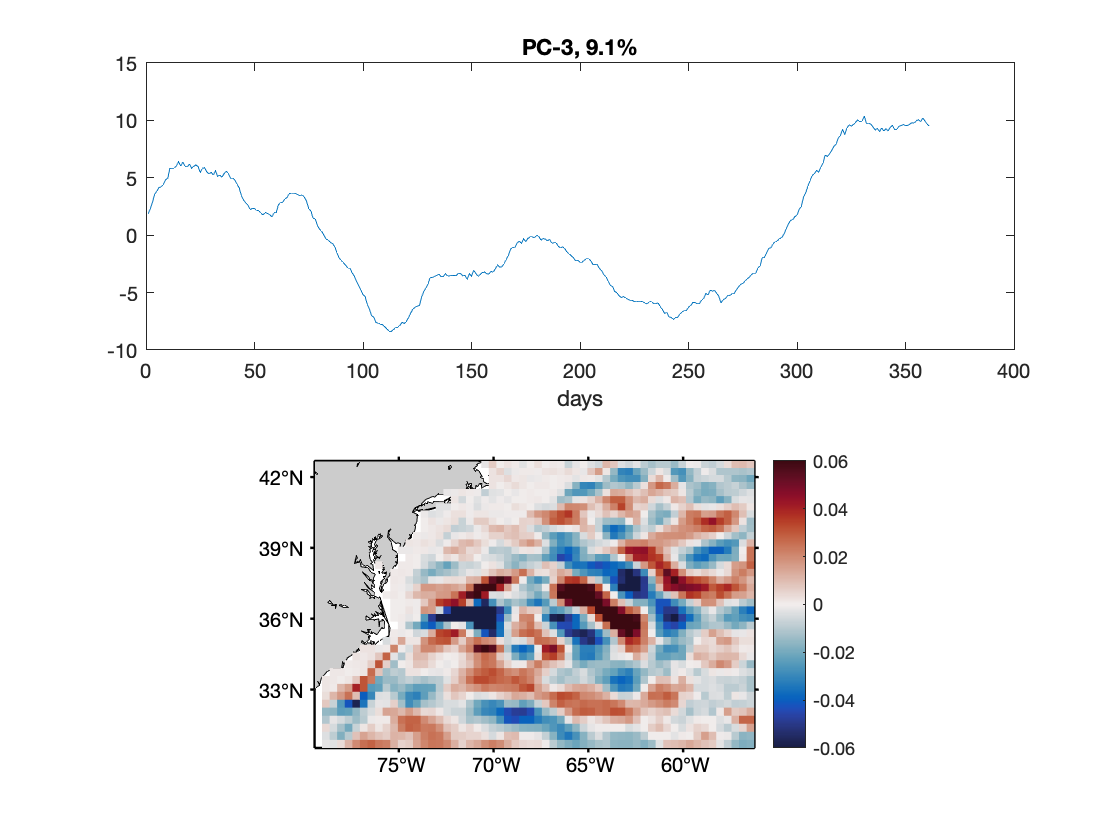

%---------------------------
% plot EOF and PC 
%---------------------------

for imod = 1:3
    figure
    subplot(211)
    plot(PC(imod,:));
    title(['PC-',num2str(imod),', ',num2str(expvar(imod),'%2.1f'),'%'])
    xlabel('days')
    
    subplot(212)
    m_proj('Equidistant Cylindrical','lon',plon1d(iA([1 ni])),'lat',plat1d(jA([1 nj])));
    m_grid('linestyle','none','tickdir','out','xtick',280:5:300,...
        'ytick',30:3:42,'linewidth',1.2);
    m_gshhs_l('patch',[.8 .8 .8]);
    hold on
    m_pcolor(ulon(jA,iA),ulat(jA,iA),EOF(:,:,imod));
    cmocean('balance')
    colorbar
    caxis([-.06 .06])
end

The covariance and correlation matrices are show below. 

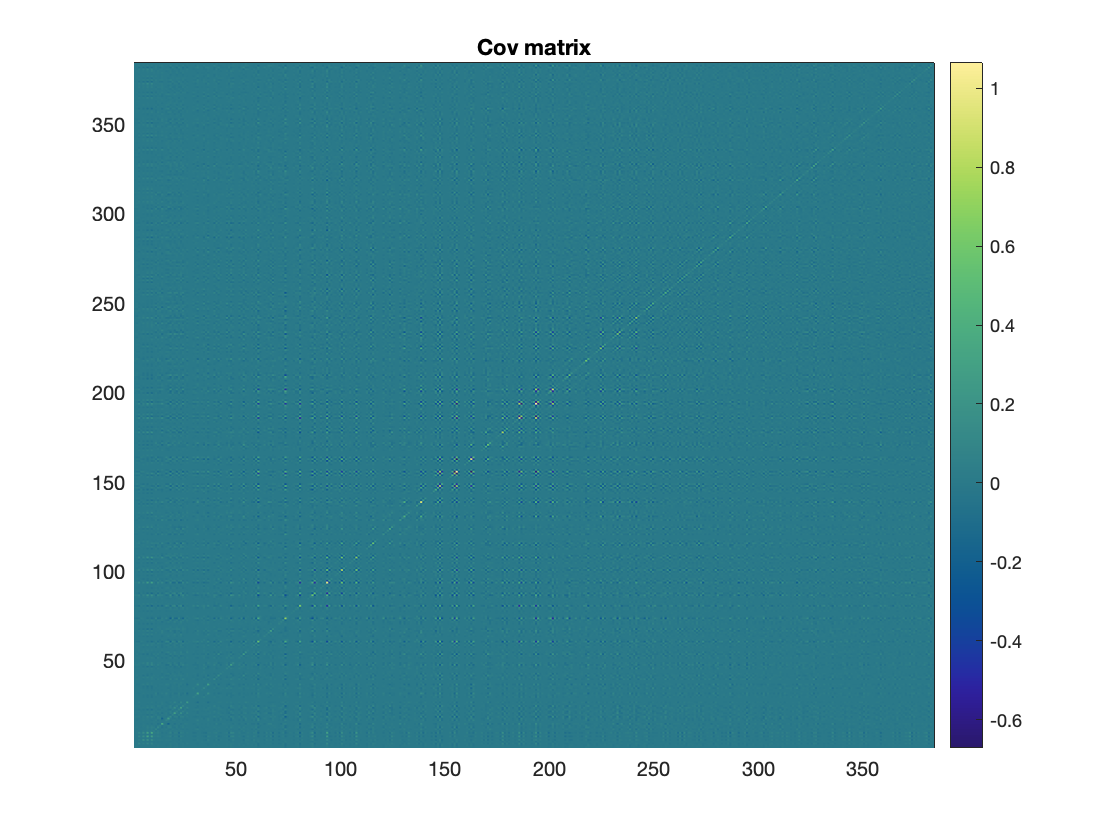

%---------------------------
%  plot cov & corr mat
%---------------------------
% cov
figure
h = pcolor(covmat(1:5:end,1:5:end));
set(h, 'EdgeColor', 'none');
cmocean('haline')
colorbar
title('Cov matrix')

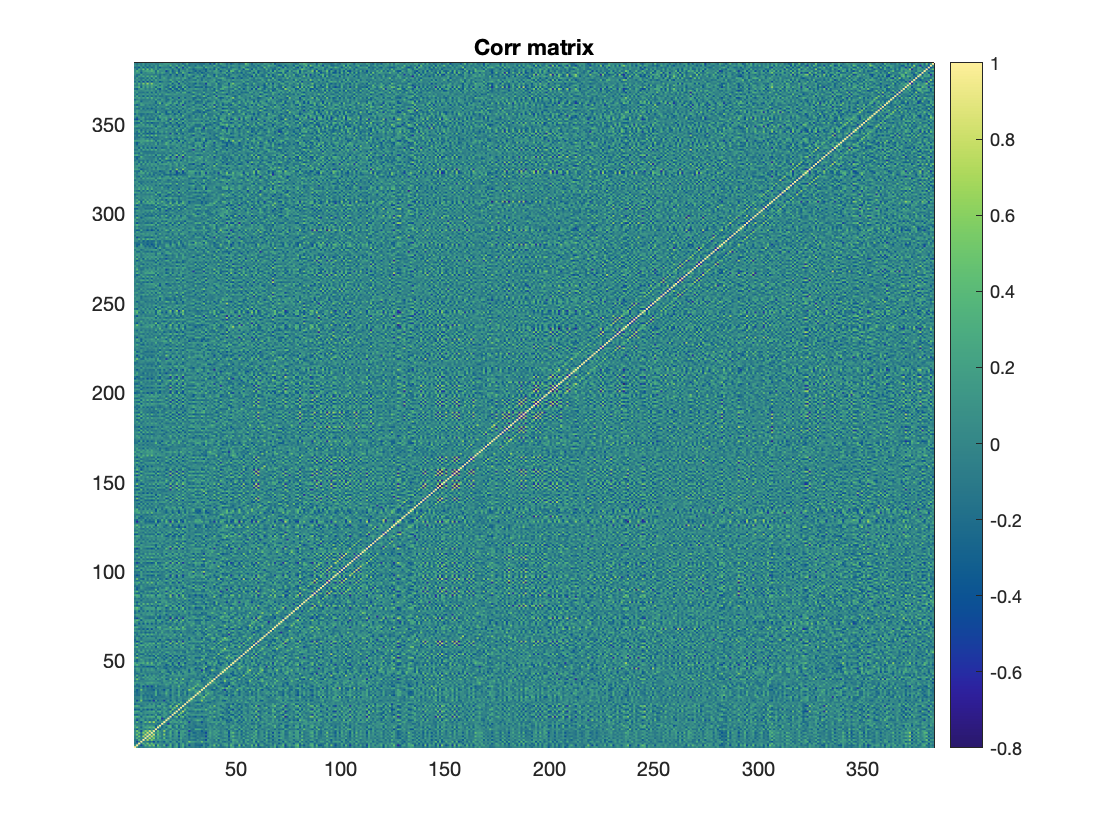

% corr
figure
h = pcolor(cormat(1:5:end,1:5:end));
set(h, 'EdgeColor', 'none');
cmocean('haline')
colorbar
caxis([-.8 1])
title('Corr matrix')